Ryan Fharenkrug

MECH 105

Homework 10

9/27/2017

Purpose: This code determines the mole fraction of x of H2O that dissociates at high tempetures.

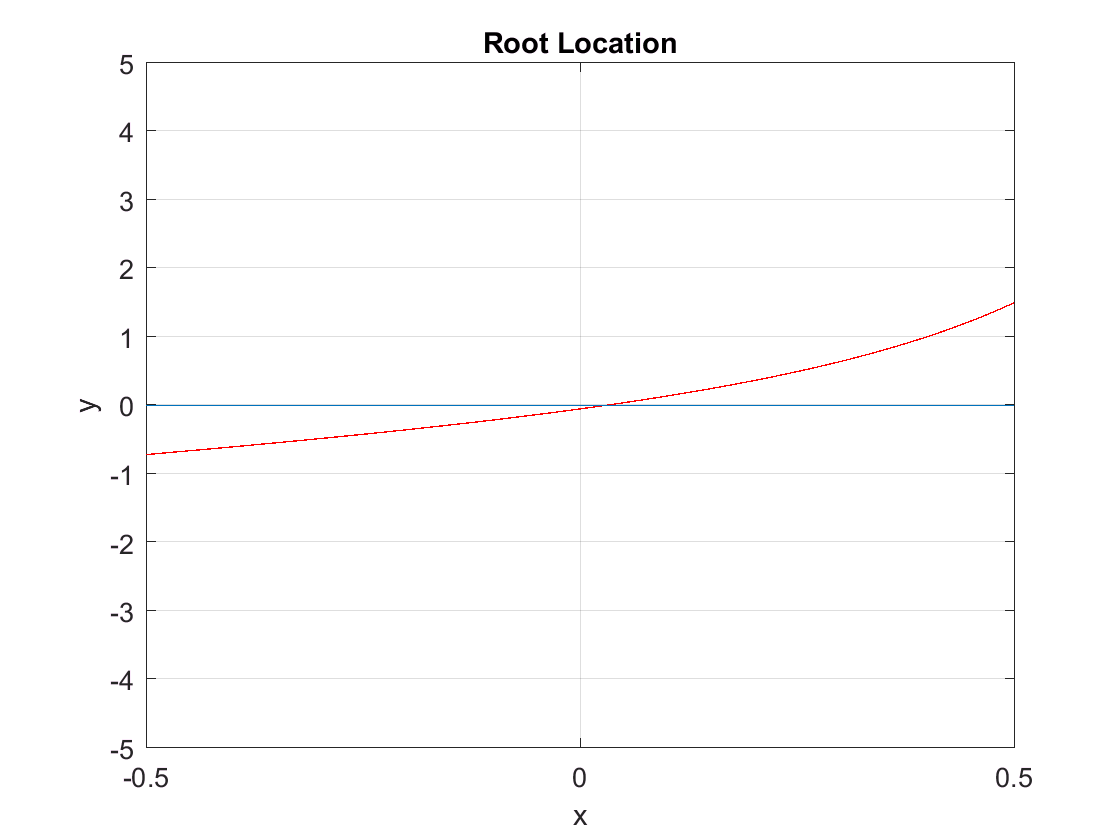

clc
clear
close all
% Total pressure of the mixture in atm.
pt=3; 
% Reactions equilibrium constant.
k=0.05;
func=@(x) ((x./(1-x)).*sqrt((2*pt)./(2+x)))-k;
fplot(func,'r');
xlim([-0.5 0.5]);
ylim([-5 5]);
refline(0,0);
grid on
title('Root Location')
xlabel('x')
ylabel('y')

% Mole fraction
mf=fzero(func,0.1)

mf =    0.028249441148471
